# Numerische Differentiation 

Wir betrachten numerische Differentiation der Funktion

    
$$f(x)=\sin (x)
$$
 

an einer Stelle $x$. Zur Approximation der zweiten Ableitung wird die Formel

   $\Delta_h(x):= \frac{f(x+h)-2 f(x)+f(x-h)}{h^2}$,

mit einer Schrittweite $h>0$ verwendet (siehe Buch).

Gezeigt werden der exakte Wert $f''(x)=-\sin(x)$, und für $k=1,\ldots,8$:

- die Schrittweite $h=10^{-k}$

- die berechnete Approximation $\tilde \Delta_h(x)$

- der Fehler $|\tilde \Delta_h(x)- f''(x)|$.

x=0.3;
format long
exakt=ddf(x)

exakt =   -0.295520206661340


disp('-------');

-------


format short
hk=zeros(8,1);   Fehlerk=zeros(8,1);
for k=1:8
    h=10^(-k)
    Approximation= (f(x+h) - 2*f(x)+f(x-h))/(h^2)
    Fehler=abs(Approximation - exakt)
    disp('---------------');
    hk(k)=h; Fehlerk(k)=Fehler;
end

h = 0.1000

Approximation = -0.2953

Fehler = 2.4618e-04

---------------


h = 0.0100

Approximation = -0.2955

Fehler = 2.4627e-06

---------------


h = 1.0000e-03

Approximation = -0.2955

Fehler = 2.4669e-08

---------------


h = 1.0000e-04

Approximation = -0.2955

Fehler = 3.9081e-09

---------------


h = 1.0000e-05

Approximation = -0.2955

Fehler = 4.8686e-07

---------------


h = 1.0000e-06

Approximation = -0.2955

Fehler = 3.4349e-05

---------------


h = 1.0000e-07

Approximation = -0.2942

Fehler = 0.0013

---------------


h = 1.0000e-08

Approximation = 0

Fehler = 0.2955

---------------


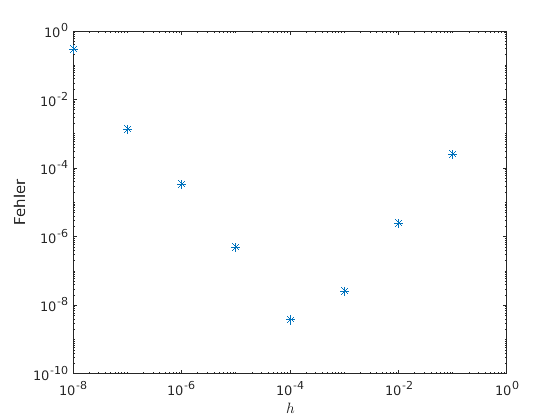

loglog(hk,Fehlerk,'*');
xlabel('$h$','Interpreter','latex');
ylabel('Fehler');

# Aktivität:

Wählen Sie einen anderen $x$-Wert und beobachten Sie die Abhängigkeit  des Fehlers von $h$.  Sie können ggf. unter diesem Abschnitt eine andere Funktion $f$ wählen.

function y=f(x)
% Funktion f
    y=sin(x);
    %y=x^5; % andere Funktion
end

function y=ddf(x)
% 2. Ableitung von f
    y=-sin(x);
    %y=20*x^3;  % andere zweite Ableitung
end
